# Nowcast State-Space Model Containing Regression Component

Consider that the linear relationship between the change in the unemployment rate and the nominal gross national product (nGNP) growth rate is of interest. Suppose the innovations of a mismeasured regression of the first difference of the unemployment rate onto the nGNP growth rate is an ARMA(1,1) series with Gaussian disturbances (that is, a regression model with ARMA(1,1) errors and measurement error). Symbolically, and in state-space form, the model is


$$\begin{array}{l}
\left[ {\begin{array}{*{20}{c}}
{{x_{1,t}}}\\
{{x_{2,t}}}
\end{array}} \right] = \left[ {\begin{array}{*{20}{c}}
\phi &\theta \\
0&0
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
{{x_{1,t - 1}}}\\
{{x_{2,t - 1}}}
\end{array}} \right] + \left[ {\begin{array}{*{20}{c}}
1\\
1
\end{array}} \right]
{{u_{t}}}\\
{y_t} - \beta {Z_t} = {x_{1,t}} + \sigma\varepsilon_t,
\end{array}$$


where:

- $x_{1,t}$ is the ARMA error series in the regression model.

- $x_{2,t}$ is a dummy state for the MA(1) effect.

- $y_{1,t}$ is the observed change in the unemployment rate being deflated by the growth rate of nGNP ($Z_t$).

- $u_{t}$ is a Gaussian series of disturbances having mean 0 and standard deviation 1.

- $\varepsilon_t$ is a Gaussian series of measurement errors with scale $\sigma$.

Load the Nelson-Plosser data set, which contains the unemployment rate and nGNP series, among other measurements.

load Data_NelsonPlosser

Preprocess the data by following this procedure:

- Remove the leading missing observations.

- Convert the nGNP series to a return series by using `price2ret`.

- Apply the first difference to the unemployment rate series.

vars = ["GNPN" "UR"];
DT = rmmissing(DataTable(:,vars));
T = size(DT,1) - 1; % Sample size after differencing

Z = [ones(T,1) price2ret(DT.GNPN)];
y = diff(DT.UR);

Though this example removes missing values, the Kalman filter accommodates series containing missing values.

Specify the coefficient matrices.

A = [NaN NaN; 0 0];
B = [1; 1];
C = [1 0];
D = NaN;

Specify the state-space model using `ssm`.

Mdl = ssm(A,B,C,D);

Fit the model to all observations except for the final 10 observations (a holdout sample). Use a random set of initial parameter values for optimization. Specify the regression component and its initial value for optimization using the `'Predictors'` and `'Beta0'` name-value arguments, respectively. Restrict the estimate of $\sigma$ to all positive, real numbers.

fh = 10;
params0 = [0.3 0.2 0.2];
[EstMdl,estParams] = estimate(Mdl,y(1:T-fh),params0,'Predictors',Z(1:T-fh,:), ...
    'Beta0',[0.1 0.2],'lb',[-Inf,-Inf,0,-Inf,-Inf]);

Method: Maximum likelihood (fmincon)
Sample size: 51
Logarithmic  likelihood:     -87.2409
Akaike   info criterion:      184.482
Bayesian info criterion:      194.141
           |      Coeff       Std Err    t Stat     Prob  
----------------------------------------------------------
 c(1)      |  -0.31780       0.37357    -0.85071  0.39494 
 c(2)      |   1.21242       0.82223     1.47455  0.14034 
 c(3)      |   0.45583       1.32970     0.34281  0.73174 
 y <- z(1) |   1.32407       0.26525     4.99179   0      
 y <- z(2) | -24.48733       1.89161   -12.94520   0      
           |                                              
           |    Final State   Std Dev     t Stat    Prob  
 x(1)      |  -0.38117       0.42842    -0.88971  0.37363 
 x(2)      |   0.23402       0.66222     0.35339  0.72380 


`EstMdl` is an `ssm` model.

Nowcast the unemployment rate into the forecast horizon. Simulate this procedure using a loop:

- Compute the current state distribution moments by filtering all in-sample observations through the estimated model.

- When an observation is available in the forecast horizon, filter it through the model. `EstMdl` does not store the regression coefficients, so you must pass them in using the name-value argument `Beta`.

- Set the current state distribution state moments to the nowcasts.

- Repeat steps 2 and 3 when new observations are available.

[currentState,currentStateCov] = update(EstMdl,y(1:T-fh), ...
    Predictors=Z(1:T-fh,:),Beta=estParams(end-1:end));
unrateF = zeros(fh,2);
unrateCovF = cell(fh,1);

for j = 1:fh
    [unrateF(j,:),unrateCovF{j}] = update(EstMdl,y(T-fh+j),currentState,currentStateCov, ...
        Predictors=Z(T-fh+j,:),Beta=estParams(end-1:end));
    currentState = unrateF(j,:)';
    currentStateCov = unrateCovF{j};
end

Plot the estimated, filtered states. Recall that the first state is the change in the unemployment rate, and the second state helps build the first.

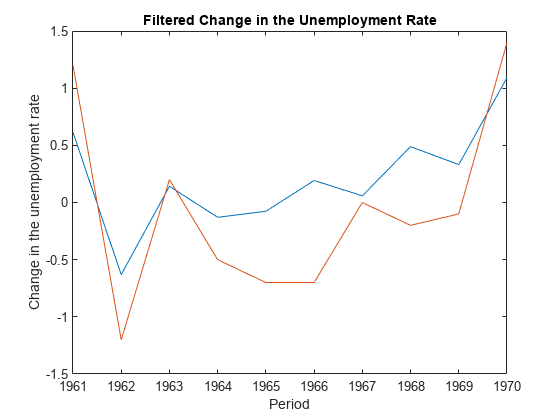

figure
plot(dates((end-fh+1):end),[unrateF(:,1) y((end-fh+1):end)]);
xlabel('Period')
ylabel('Change in the unemployment rate')
title('Filtered Change in the Unemployment Rate')

*Copyright 2021 The MathWorks, Inc.*